# Integrate and Animate Double Pendulum

clear;clc;

l1 = 5; l2 = 5; 
c1 = l1/2; c2 = l2/2; 
m1 = 0.5; m2 = 0.5; 
I1 = 1/12 * m1 * l1^2; I2 = 1/12 * m2 * l2^2;
g = 9.81;

## Integrate

T =30;
% IC has 0 angular velocity thus 0 KE. Rods have 0 y-distance from fixed
% frame so 0 PE. Thus total energy of the system T+V should be 0. This will
% not be true with an external forcing i.e when tau != 0.

% No external force tau = 0
s0 = [pi/2; 0; 0; 0];
[t,s] = ode45(@(t,s) double_pendulum_dynamics(s(1),s(2),s(3),s(4),0,0),[0 T],s0);

% Spring joint at tau2 = -50*(th2-pi/2)
% s0 = [pi/2; pi/2; 0; 0];
% [t,s] = ode45(@(t,s) double_pendulum_dynamics(s(1),s(2),s(3),s(4),0,-50*(s(2)-pi/2)),[0 T],s0);

% Spring joint at tau2 = -10*th2d
% s0 = [pi/2; pi/2; 0; 0];
% [t,s] = ode45(@(t,s) double_pendulum_dynamics(s(1),s(2),s(3),s(4),0,-10*s(4)),[0 T],s0);

## Animate

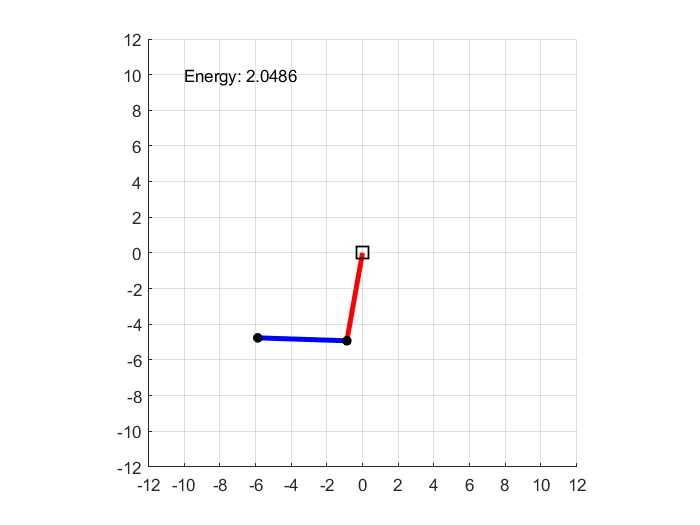

fps = 10;
tq = linspace(0,t(end), round(t(end)*fps));
data = zeros(length(tq),size(s,2));
for n=1:size(s,2)
    data(:,n) = interp1(t,s(:,n),tq);
end

O1 = [0 0];
for k=1:size(data,1)
    sk = data(k,:);
    th1 = sk(1);
    th2 = sk(2);
    th1d = sk(3);
    th2d = sk(4);
    % E = T+V
    E = (981*sin(th1)*sin(th2))/80 - (981*cos(th1)*cos(th2))/80 - (2943*cos(th1))/80 + (th2d*((5*cos(th1)*cos(th2))/2 - (5*sin(th1)*sin(th2))/2) + th1d*(5*cos(th1) + (5*cos(th1)*cos(th2))/2 - (5*sin(th1)*sin(th2))/2))*((th2d*((5*cos(th1)*cos(th2))/2 - (5*sin(th1)*sin(th2))/2))/4 + (th1d*(5*cos(th1) + (5*cos(th1)*cos(th2))/2 - (5*sin(th1)*sin(th2))/2))/4) + (25*th1d^2*cos(th1)^2)/16 + (th2d*((5*cos(th1)*sin(th2))/2 + (5*cos(th2)*sin(th1))/2) + th1d*(5*sin(th1) + (5*cos(th1)*sin(th2))/2 + (5*cos(th2)*sin(th1))/2))*((th2d*((5*cos(th1)*sin(th2))/2 + (5*cos(th2)*sin(th1))/2))/4 + (th1d*(5*sin(th1) + (5*cos(th1)*sin(th2))/2 + (5*cos(th2)*sin(th1))/2))/4) + (25*th1d^2*sin(th1)^2)/16 + (25*(th1d + th2d)^2)/48 + (25*th1d^2)/48;
    joint_pos = double_pendulum_kinematics(th1,th2,l1,l2);
    O2 = joint_pos(:,1);
    O3 = joint_pos(:,2);
    grid on;
    hold on;  
    h1 = line([O1(1) O2(1)], [O1(2) O2(2)], "LineWidth", 3, 'Color', 'red');
    h2 = line([O2(1) O3(1)], [O2(2) O3(2)], "LineWidth", 3, 'Color', 'blue');
    h3 = plot(O1(1), O1(2), 's', 'MarkerSize', 10, "LineWidth", 1, 'Color', 'black');
    h4 = plot(O2(1), O2(2), '.', 'MarkerSize', 20, 'Color', 'black');
    h5 = plot(O3(1), O3(2), '.', 'MarkerSize', 20, 'Color', 'black');
    h6 = text(-10, 10, ['Energy: ' num2str(E)]);
    axis([-12 12 -12 12]);
    xticks(-12:2:12);
    yticks(-12:2:12);
    daspect([1 1 1]);
    pause(0.1);
    if k ~= size(data,1)
        delete(h1)
        delete(h2)
        delete(h3)
        delete(h4)
        delete(h5)
        delete(h6)
    end
end

% The positive energy accumulation over time states that the integration is
% not perfect. This is maybe due to the error in integration over time or due to interpolation errors.
% The system is chaotic and hence a more sensitive integrator (symplectic integrator) 
% is required for near perfect simulation. Ideally a perfect simulation should keep this energy at 0 
% abiding by the law of conservation of energy. https://youtu.be/RG9waSjj2dc?t=877